# Laboratory 3

Problems

Consider the fixed parts: Kf = 2, Tf=2sec with given performance sets.

%% a
clear variables; 

Kf = 2;
Tf = 2;
Estp = 0;
ts = 4.5;
sigma = 0.13;
cv = 0.2;
wb = 2;

zeta = abs(log(sigma))/sqrt(log(sigma)^2+pi^2);
wn = 4/ts/zeta;
Ho = tf([0 0 wn^2],[1 2*zeta*wn wn^2])

Ho =
 
          2.664
  ---------------------
  s^2 + 1.778 s + 2.664
 
Continuous-time transfer function.



Hf = tf(2,[2 1 0])

Hf =
 
      2
  ---------
  2 s^2 + s
 
Continuous-time transfer function.



Hr = (Ho/(1-Ho))/Hf

Hr =
 
  5.327 s^4 + 12.13 s^3 + 18.92 s^2 + 7.095 s
  -------------------------------------------
    2 s^4 + 7.111 s^3 + 11.65 s^2 + 9.47 s
 
Continuous-time transfer function.



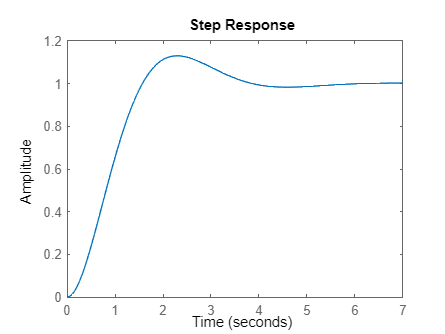


step(feedback(Hf*Hr,1))


cv = sigma/2/zeta

cv = 0.1193

wb = wn*sqrt(1-2*zeta^2+sqrt(2-4*zeta^2+4*zeta^4))

wb = 1.9897


%% b
estp = 0;
ts = 4.5;
sigma = 0.12;
cv = 1;
wb = 2;

zeta = abs(log(sigma))/sqrt(log(sigma)^2+pi^2);
wn = 4/ts/zeta;
Ho = tf([0 0 wn^2],[1 2*zeta*wn wn^2])

Ho =
 
          2.525
  ---------------------
  s^2 + 1.778 s + 2.525
 
Continuous-time transfer function.



Hf = tf(2,[2 1 0])

Hf =
 
      2
  ---------
  2 s^2 + s
 
Continuous-time transfer function.



Hr = (Ho/(1-Ho))/Hf

Hr =
 
  5.05 s^4 + 11.5 s^3 + 17.24 s^2 + 6.375 s
  -----------------------------------------
   2 s^4 + 7.111 s^3 + 11.37 s^2 + 8.977 s
 
Continuous-time transfer function.



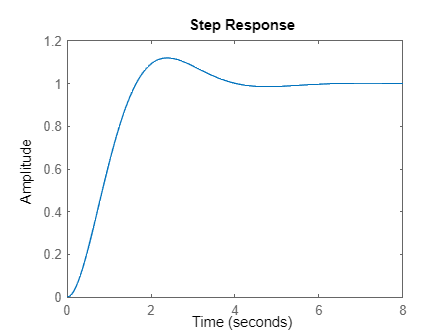


step(feedback(Hf*Hr,1))


cv = sigma/2/zeta

cv = 0.1073

wb = wn*sqrt(1-2*zeta^2+sqrt(2-4*zeta^2+4*zeta^4))

wb = 1.9079


%% c
estp = 0;
ts = 6.5;
sigma = 0.1;
cv = 1.5;
wb = 1.2;

zeta = abs(log(sigma))/sqrt(log(sigma)^2+pi^2);
wn = 4/ts/zeta;
Ho = tf([0 0 wn^2],[1 2*zeta*wn wn^2])

Ho =
 
          1.084
  ---------------------
  s^2 + 1.231 s + 1.084
 
Continuous-time transfer function.



Hf = tf(2,[2 1 0])

Hf =
 
      2
  ---------
  2 s^2 + s
 
Continuous-time transfer function.



Hr = (Ho/(1-Ho))/Hf

Hr =
 
  2.167 s^4 + 3.751 s^3 + 3.682 s^2 + 1.174 s
  -------------------------------------------
    2 s^4 + 4.923 s^3 + 5.197 s^2 + 2.667 s
 
Continuous-time transfer function.



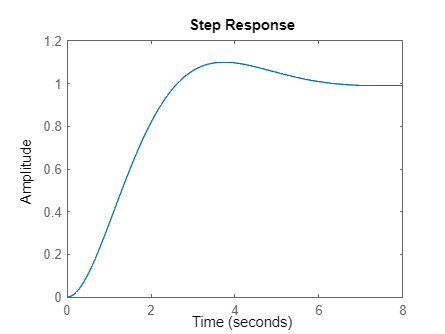


step(feedback(Hf*Hr,1))


cv = sigma/2/zeta

cv = 0.0846

wb = wn*sqrt(1-2*zeta^2+sqrt(2-4*zeta^2+4*zeta^4))

wb = 1.2075